# Frequency-Domain Analysis of Discrete Signals

From DTFT to FFT, and why a signal's shape always carries frequency information.

Learning outcomes 1. Compute and interpret the DTFT X(w) of x[n] (continuous, 2*pi-periodic in w). 2. Relate the DFT/FFT X[k] to samples of the DTFT, and handle resolution, zero-padding and leakage. 3. Use the spectrum in practice: peaks, PSD, filtering, spectral features, delay estimation. 4. Explain that morphology (shape) encodes frequency content, not only "how often" an event occurs.

Only base MATLAB is required (no toolboxes).

clear; clc; close all;
rng(1);   % reproducible random numbers

## PART 1 - The DTFT: from x[n] to a continuous X(w)

Definition: X(w) = sum over all n of x[n] * exp(-j*w*n)

Key facts - w is in rad/sample and X(w) is continuous in w. - X(w) is periodic with period 2*pi, so only one period is needed. - Real x[n] gives `X(w)` even and angle(X(w)) odd. - Convergence requires that x[n] is absolutely summable (or a limit in the distributional sense).

MATLAB cannot represent a continuous variable, so we evaluate the sum on a very dense grid of w. The sum becomes one matrix product.

## 1.1 DTFT of a decaying exponential: x[n] = 0.8^n u[n]

Closed form: X(w) = 1 / (1 - 0.8*exp(-j*w))

n = 0:49;                       % finite record (0.8^50 is about 1e-5, negligible)
x = 0.8.^n;
w = linspace(-pi, pi, 1024);    % dense frequency grid

X      = x * exp(-1j * n(:) * w);          % DTFT as a (1 x Nn)*(Nn x Nw) product
Xtrue  = 1 ./ (1 - 0.8*exp(-1j*w));        % analytic result

fprintf('Max |numeric - analytic| = %.2e\n', max(abs(X - Xtrue)));

Max |numeric - analytic| = 7.14e-05


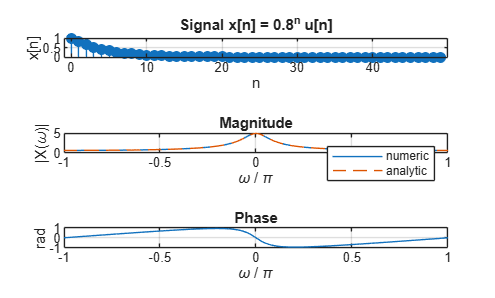


figure
tiledlayout(3,1)
nexttile, stem(n, x, 'filled'), grid on
xlabel('n'), ylabel('x[n]'), title('Signal x[n] = 0.8^n u[n]')
nexttile, plot(w/pi, abs(X), w/pi, abs(Xtrue), '--'), grid on
xlabel('\omega / \pi'), ylabel('|X(\omega)|'), title('Magnitude'), legend('numeric','analytic')
nexttile, plot(w/pi, angle(X)), grid on
xlabel('\omega / \pi'), ylabel('rad'), title('Phase')

## 1.2 Periodicity of the DTFT

Evaluate over three periods. The pattern repeats every 2*pi because exp(-j*(w+2*pi)*n) = exp(-j*w*n) for integer n.

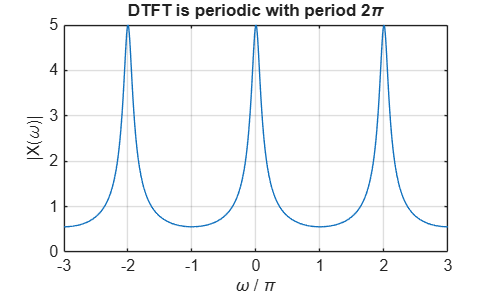

w3 = linspace(-3*pi, 3*pi, 3072);
X3 = x * exp(-1j * n(:) * w3);

figure
plot(w3/pi, abs(X3)), grid on
xlabel('\omega / \pi'), ylabel('|X(\omega)|')
title('DTFT is periodic with period 2\pi')

## 1.3 Window length vs spectral shape (rectangular pulses)

A rectangular pulse of length L has `X(w)` = `sin(w*L/2) / sin(w/2)` (Dirichlet kernel). Main-lobe width is 4*pi/L: a longer pulse in n gives a narrower spectrum in w.

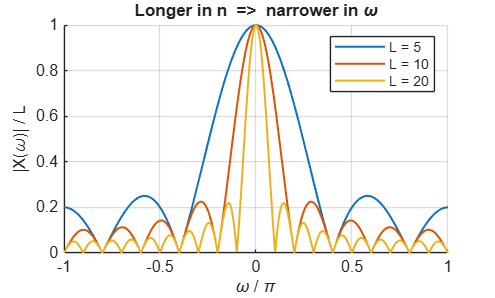

figure, hold on
for L = [5 10 20]
    xr = ones(1, L);
    Xr = xr * exp(-1j * (0:L-1)' * w);
    plot(w/pi, abs(Xr)/L, 'DisplayName', sprintf('L = %d', L), 'LineWidth', 1.2);
end
grid on, xlabel('\omega / \pi'), ylabel('|X(\omega)| / L')
title('Longer in n  =>  narrower in \omega'), legend show

## 1.4 Time shift = linear phase

x[n - n0]  [--](http://--) exp(-j*w*n0) * X(w). The magnitude is unchanged; only phase changes.

n0 = 5;
x2 = [zeros(1, n0), x];
n2 = 0:numel(x2)-1;
X2 = x2 * exp(-1j * n2(:) * w);

fprintf('Magnitude unchanged by delay: max difference = %.2e\n', max(abs(abs(X2) - abs(X))));

Magnitude unchanged by delay: max difference = 2.66e-15


fprintf('Phase rule holds: max |X2 - X*exp(-jw*n0)| = %.2e\n', max(abs(X2 - X.*exp(-1j*w*n0))));

Phase rule holds: max |X2 - X*exp(-jw*n0)| = 3.22e-15


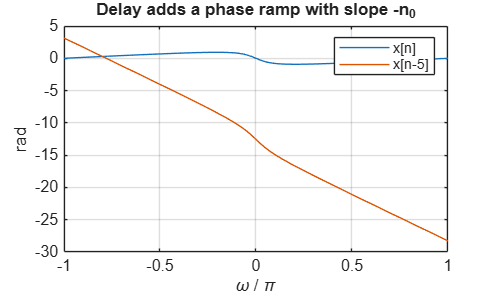


figure
plot(w/pi, unwrap(angle(X)), w/pi, unwrap(angle(X2))), grid on
xlabel('\omega / \pi'), ylabel('rad'), legend('x[n]', 'x[n-5]')
title('Delay adds a phase ramp with slope -n_0')

## PART 2 - The DFT via the FFT: from x[n] to a discrete X[k]

For a length-N record, the DFT is

Interpretation: the DFT is the DTFT of the N-point record sampled at w_k = 2*pi*k/N. The FFT is a fast algorithm (O(N log N)) for the same numbers, not a different transform.

Frequency axis: bin k corresponds to f_k = k*fs/N Hz, resolution df = fs/N.

## 2.1 The DFT samples the DTFT

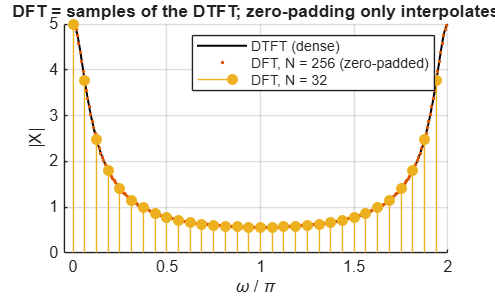

N  = 32;
n  = 0:N-1;
x  = 0.8.^n;

Xk   = fft(x);                          % N samples
wk   = 2*pi*(0:N-1)/N;
wd   = linspace(0, 2*pi, 1024);
Xd   = x * exp(-1j * n(:) * wd);        % dense DTFT of the same N-point record
Xz   = fft(x, 256);                     % zero-padded to 256 points
wz   = 2*pi*(0:255)/256;

figure, hold on
plot(wd/pi, abs(Xd), 'k', 'LineWidth', 1.2, 'DisplayName', 'DTFT (dense)')
plot(wz/pi, abs(Xz), '.', 'DisplayName', 'DFT, N = 256 (zero-padded)')
stem(wk/pi, abs(Xk), 'filled', 'DisplayName', 'DFT, N = 32')
grid on, xlabel('\omega / \pi'), ylabel('|X|'), legend show
title('DFT = samples of the DTFT; zero-padding only interpolates')

## 2.2 The DFT as a matrix, and why the FFT matters

X = W*x with W(k,n) = exp(-j*2*pi*k*n/N).

N = 64;
x = randn(N, 1);
W = exp(-1j * 2*pi * (0:N-1)' * (0:N-1) / N);
fprintf('Matrix DFT vs fft: max difference = %.2e\n', max(abs(W*x - fft(x))));

Matrix DFT vs fft: max difference = 2.19e-13


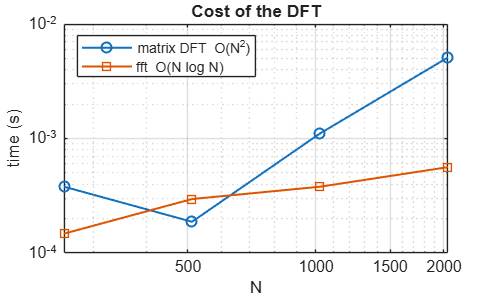


Ns   = 2.^(8:11);
tDFT = zeros(size(Ns));
tFFT = zeros(size(Ns));
for i = 1:numel(Ns)
    Ni = Ns(i);
    xi = randn(Ni, 1);
    Wi = exp(-1j * 2*pi * (0:Ni-1)' * (0:Ni-1) / Ni);
    tic; for r = 1:5, Wi*xi; end, tDFT(i) = toc/5;
    tic; for r = 1:5, fft(xi); end, tFFT(i) = toc/5;
end
figure
loglog(Ns, tDFT, 'o-', Ns, tFFT, 's-', 'LineWidth', 1.2), grid on
xlabel('N'), ylabel('time (s)'), legend('matrix DFT  O(N^2)', 'fft  O(N log N)', 'Location', 'northwest')
title('Cost of the DFT')

## 2.3 Building a correct frequency axis

fft returns bins 0..fs (second half = negative frequencies). Use fftshift for a two-sided view, or keep only the first N/2+1 bins for real signals.

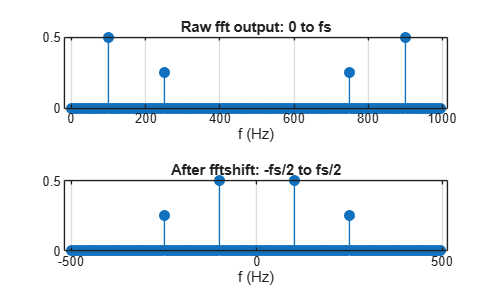

fs = 1000;  N = 200;
t  = (0:N-1)/fs;
x  = cos(2*pi*100*t) + 0.5*sin(2*pi*250*t);

X  = fft(x);
f  = (0:N-1)*fs/N;                       % 0 ... fs - df
fc = (-N/2:N/2-1)*fs/N;                  % -fs/2 ... fs/2 - df

figure
tiledlayout(2,1)
nexttile, stem(f, abs(X)/N, 'filled'), grid on, xlabel('f (Hz)'), title('Raw fft output: 0 to fs')
nexttile, stem(fc, abs(fftshift(X))/N, 'filled'), grid on, xlabel('f (Hz)'), title('After fftshift: -fs/2 to fs/2')

## 2.4 Resolution and spectral leakage

Leakage-free only when the record holds an integer number of periods. Otherwise energy spreads over many bins. A taper (Hann window) reduces the spread at the cost of a wider main lobe.

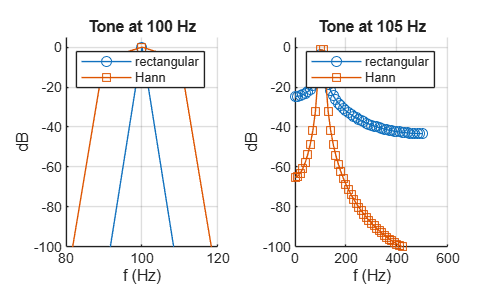

fs = 1000;  N = 100;  t = (0:N-1)/fs;       % df = 10 Hz
hann = 0.5*(1 - cos(2*pi*(0:N-1)/N));       % periodic Hann window
f1   = (0:N/2)*fs/N;

figure
tiledlayout(1,2)
for f0 = [100 105]       % 100 Hz sits exactly on bin 10; 105 Hz falls between bins
    x  = sin(2*pi*f0*t);
    Ar = abs(fft(x))/N*2;                   Ar = Ar(1:N/2+1);
    Ah = abs(fft(x.*hann))/sum(hann)*2;     Ah = Ah(1:N/2+1);
    nexttile, hold on
    plot(f1, 20*log10(max(Ar,1e-6)), 'o-', 'DisplayName', 'rectangular')
    plot(f1, 20*log10(max(Ah,1e-6)), 's-', 'DisplayName', 'Hann')
    grid on, ylim([-100 5]), xlabel('f (Hz)'), ylabel('dB'), legend show
    title(sprintf('Tone at %d Hz', f0))
end

## PART 3 - Practical operations in the frequency domain

What does the spectrum tell us about a signal? - WHERE energy lives (peaks) -> periodicities, oscillation frequencies - HOW it is spread (flat vs peaked) -> noise-like vs tonal - Phase -> timing, delay, shape And we can modify it (filter) by multiplying X[k] by a mask.

## 3.1 Reading a noisy spectrum: single-sided amplitude and peak picking

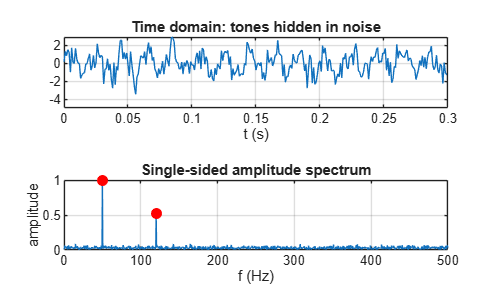

fs = 1000;  N = 2000;  t = (0:N-1)/fs;
x  = 1.0*sin(2*pi*50*t) + 0.5*sin(2*pi*120*t) + 0.8*randn(1, N);

A = abs(fft(x))/N;
A = A(1:N/2+1);   A(2:end-1) = 2*A(2:end-1);     % single-sided amplitude
f = (0:N/2)*fs/N;

thr = 8*median(A);                                % crude noise-floor based threshold
core = A(2:end-1);
isPeak = core > A(1:end-2) & core > A(3:end) & core > thr;
pk = find(isPeak) + 1;

figure
tiledlayout(2,1)
nexttile, plot(t(1:300), x(1:300)), grid on, xlabel('t (s)'), title('Time domain: tones hidden in noise')
nexttile, plot(f, A), hold on, plot(f(pk), A(pk), 'ro', 'MarkerFaceColor', 'r'), grid on
xlabel('f (Hz)'), ylabel('amplitude'), title('Single-sided amplitude spectrum')


fprintf('Detected peaks:\n');

Detected peaks:


for i = 1:numel(pk), fprintf('  f = %6.1f Hz, amplitude = %.2f\n', f(pk(i)), A(pk(i))); end

  f =   50.0 Hz, amplitude = 0.99
  f =  120.0 Hz, amplitude = 0.52


## 3.2 Power spectral density: periodogram vs averaged periodogram

The raw periodogram is noisy: its variance does not shrink as N grows. Averaging windowed segments (Welch's idea) trades resolution for variance.

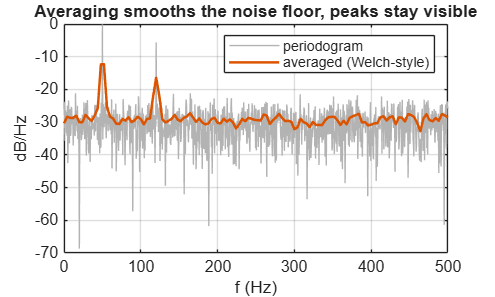

[Pw, fw] = welchSimple(x, 250, fs);          % segments of 250 samples, 50% overlap
P0 = abs(fft(x)).^2/(fs*N);   P0 = P0(1:N/2+1);   P0(2:end-1) = 2*P0(2:end-1);

figure
plot(f, 10*log10(P0), 'Color', [0.7 0.7 0.7]), hold on
plot(fw, 10*log10(Pw), 'LineWidth', 1.5), grid on
xlabel('f (Hz)'), ylabel('dB/Hz'), legend('periodogram', 'averaged (Welch-style)')
title('Averaging smooths the noise floor, peaks stay visible')

## 3.3 Filtering by editing X[k]

Keep bins below 80 Hz. The mask must be symmetric (bin k and N-k) so the result stays real.

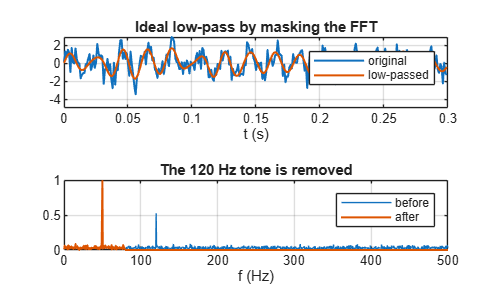

X  = fft(x);
fk = (0:N-1)*fs/N;
fa = min(fk, fs - fk);                    % |frequency| of each bin
mask = double(fa <= 80);
y  = real(ifft(X .* mask));

figure
tiledlayout(2,1)
nexttile, plot(t(1:300), x(1:300), t(1:300), y(1:300), 'LineWidth', 1.2), grid on
xlabel('t (s)'), legend('original', 'low-passed'), title('Ideal low-pass by masking the FFT')
nexttile
plot(f, A), hold on
Y = abs(fft(y))/N; Y = Y(1:N/2+1); Y(2:end-1) = 2*Y(2:end-1);
plot(f, Y, 'LineWidth', 1.2), grid on, xlabel('f (Hz)'), legend('before', 'after')
title('The 120 Hz tone is removed')


% Note: a hard mask is a rectangle in frequency = a sinc in time, so it rings
% (Gibbs). Smooth masks or windowed designs avoid this.

## 3.4 Spectral features separate classes of signals

Spectral centroid : "center of mass" of the power spectrum Spectral bandwidth : spread around the centroid Spectral entropy : 0 = a single line, 1 = perfectly flat (white)

fs = 1000;  N = 2000;  t = (0:N-1)/fs;  T = N/fs;
sigs = {
    sin(2*pi*50*t)
    sign(sin(2*pi*50*t))
    randn(1, N)
    sin(2*pi*(10*t + 190/(2*T)*t.^2))      % linear chirp 10 -> 200 Hz
    [zeros(1,N/2-1), 1, zeros(1,N/2)]      % single impulse
};
names = {'Sine 50 Hz'; 'Square 50 Hz'; 'White noise'; 'Chirp 10-200 Hz'; 'Impulse'};

fc = zeros(5,1);  bw = zeros(5,1);  H = zeros(5,1);
for i = 1:5
    [fc(i), bw(i), H(i)] = specFeatures(sigs{i}, fs);
end
disp(table(names, round(fc,1), round(bw,1), round(H,3), ...
    'VariableNames', {'Signal','Centroid_Hz','Bandwidth_Hz','Entropy'}))

          Signal           Centroid_Hz    Bandwidth_Hz    Entropy
    ___________________    ___________    ____________    _______

    {'Sine 50 Hz'     }          50              0             0 
    {'Square 50 Hz'   }        83.4             84         0.193 
    {'White noise'    }       246.6          143.3          0.94 
    {'Chirp 10-200 Hz'}         105           54.9         0.864 
    {'Impulse'        }       250.3          144.3             1 



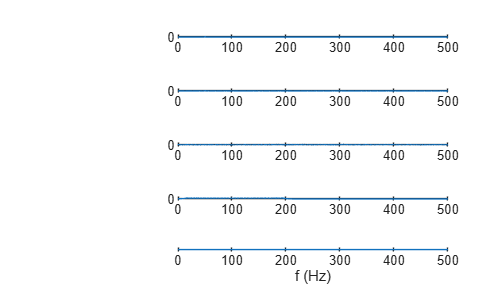


figure
tiledlayout(5,1)
for i = 1:5
    Xi = abs(fft(sigs{i}))/N;  Xi = Xi(1:N/2+1);
    nexttile, plot((0:N/2)*fs/N, Xi), grid on, ylabel(names{i}, 'Rotation', 0, 'HorizontalAlignment', 'right')
end
xlabel('f (Hz)')

## 3.5 Using phase: delay estimation with the cross-spectrum

Correlation in n = multiplication in frequency: r = ifft( conj(X) .* Y ). The location of the peak of r gives the delay between two noisy copies.

N = 1024;
s = randn(1, N);
d = 37;                                         % true delay in samples
a = s + 0.5*randn(1, N);
b = circshift(s, d) + 0.5*randn(1, N);

r = real(ifft(conj(fft(a)) .* fft(b)));
[~, idx] = max(r);
fprintf('True delay = %d samples, estimated = %d samples\n', d, idx-1);

True delay = 37 samples, estimated = 37 samples


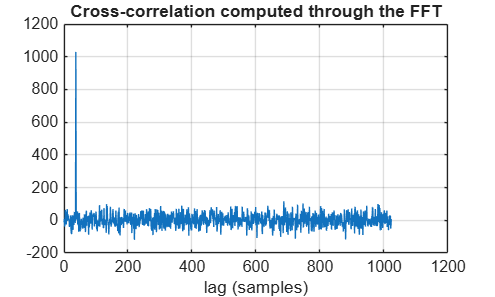


figure
plot(0:N-1, r), grid on, xlabel('lag (samples)'), title('Cross-correlation computed through the FFT')

## PART 4 - Morphology always carries frequency information

Common misconception: "frequency analysis is about how often something happens". Actually, two separate pieces of information live in a spectrum:

A single non-repeating event has no "rate" at all, yet it has a full spectrum.

## 4.1 One event, no repetition, clear frequency: a damped oscillation

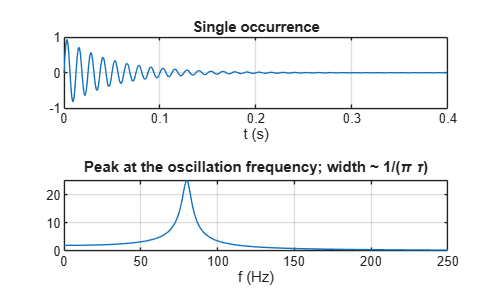

fs = 1000;  N = 4096;  t = (0:N-1)/fs;
f0 = 80;  tau = 0.05;
x  = exp(-t/tau) .* sin(2*pi*f0*t);               % a single "ring"

X  = abs(fft(x));  f = (0:N/2)*fs/N;

figure
tiledlayout(2,1)
nexttile, plot(t(1:400), x(1:400)), grid on, xlabel('t (s)'), title('Single occurrence')
nexttile, plot(f, X(1:N/2+1)), xlim([0 250]), grid on, xlabel('f (Hz)')
title('Peak at the oscillation frequency; width ~ 1/(\pi \tau)')

## 4.2 Shape determines harmonic content: building a square wave

Square wave = sum over odd k of (4/pi) * sin(2*pi*k*f0*t)/k. The sharp edges require many high harmonics. Truncation produces the Gibbs overshoot.

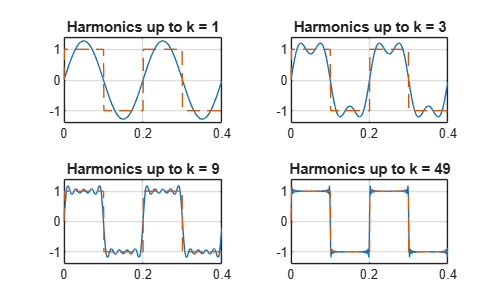

fs = 1000;  f0 = 5;  t = 0:1/fs:0.4-1/fs;
figure
tiledlayout(2,2)
for K = [1 3 9 49]
    y = zeros(size(t));
    for k = 1:2:K, y = y + (4/pi)*sin(2*pi*k*f0*t)/k; end
    nexttile, plot(t, y, t, sign(sin(2*pi*f0*t)), '--'), grid on, ylim([-1.4 1.4])
    title(sprintf('Harmonics up to k = %d', K))
end

## 4.3 Same fundamental, different shape, different harmonic decay

Square and sawtooth have smooth-ish decay 1/k at jumps; the triangle has no jumps (only slope changes) so it decays faster, 1/k^2. Rule of thumb: the smoother the waveform, the faster its spectrum decays.

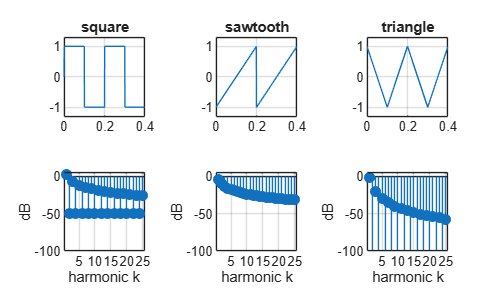

fs = 1000;  f0 = 5;  N = 2000;  t = (0:N-1)/fs;     % 10 whole periods, bin-centered
saw = 2*mod(f0*t, 1) - 1;
tri = 2*abs(saw) - 1;
sq  = sign(sin(2*pi*f0*t));
shapes = {sq, saw, tri};  labels = {'square', 'sawtooth', 'triangle'};

figure
tiledlayout(2,3)
for i = 1:3
    nexttile, plot(t(1:400), shapes{i}(1:400)), grid on, title(labels{i}), ylim([-1.3 1.3])
end
kk = 1:25;
for i = 1:3
    Ai = abs(fft(shapes{i}))/N*2;
    Hk = Ai(10*kk + 1);                          % harmonic k sits at f = k*f0 -> bin 10k
    nexttile, stem(kk, 20*log10(max(Hk, 1e-6)), 'filled'), grid on, ylim([-100 5])
    xlabel('harmonic k'), ylabel('dB')
end

## 4.4 Same magnitude spectrum, different morphology: phase matters

The shape in time is stored mostly in phase. Keep `X` and scramble the phase: the "same amount" of each frequency, but a totally different waveform. Keep only the phase (unit magnitude): edges and structure survive.

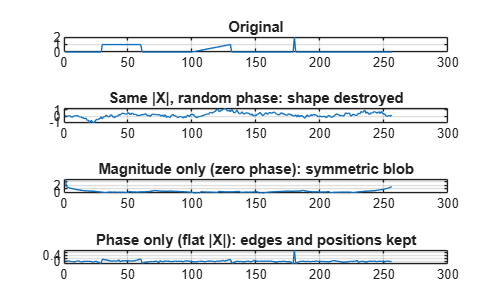

N = 256;
x = zeros(1, N);
x(30:60)    = 1;                       % a box
x(100:130)  = linspace(0, 1, 31);      % a ramp
x(180)      = 2;                       % a spike

X = fft(x);
phi = 2*pi*rand(N/2-1, 1) - pi;
phiFull = [0; phi; 0; -flipud(phi)];                  % conjugate-symmetric random phase
x_randphase = real(ifft(abs(X(:)) .* exp(1j*phiFull)));
x_magonly   = real(ifft(abs(X)));                     % zero phase
x_phaseonly = real(ifft(exp(1j*angle(X))));           % unit magnitude

figure
tiledlayout(4,1)
nexttile, plot(x),             grid on, title('Original')
nexttile, plot(x_randphase),   grid on, title('Same |X|, random phase: shape destroyed')
nexttile, plot(x_magonly),     grid on, title('Magnitude only (zero phase): symmetric blob')
nexttile, plot(x_phaseonly),   grid on, title('Phase only (flat |X|): edges and positions kept')

## 4.5 Width in time vs width in frequency (uncertainty)

A narrow pulse has a wide spectrum; a wide pulse has a narrow spectrum. Sharp features = high frequency content, by construction.

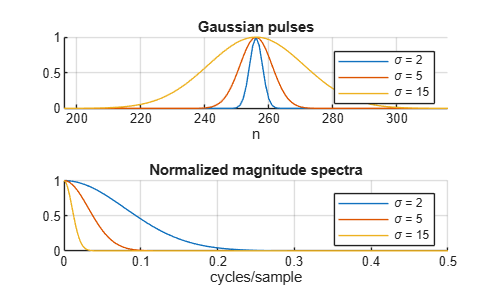

N = 512;  n = 0:N-1;
figure
tiledlayout(2,1)
nexttile, hold on
nexttile, hold on
for s = [2 5 15]
    g = exp(-0.5*((n - N/2)/s).^2);
    G = abs(fft(g));  G = G/max(G);
    nexttile(1), plot(n, g, 'DisplayName', sprintf('\\sigma = %d', s))
    nexttile(2), plot((0:N/2)/N, G(1:N/2+1), 'DisplayName', sprintf('\\sigma = %d', s))
end
nexttile(1), grid on, xlim([N/2-60 N/2+60]), xlabel('n'), title('Gaussian pulses'), legend show
nexttile(2), grid on, xlabel('cycles/sample'), title('Normalized magnitude spectra'), legend show

## 4.6 Occurrence vs morphology: a heartbeat-like signal

One beat has a morphology (P wave, sharp QRS, T wave). A train of beats adds an occurrence rate.

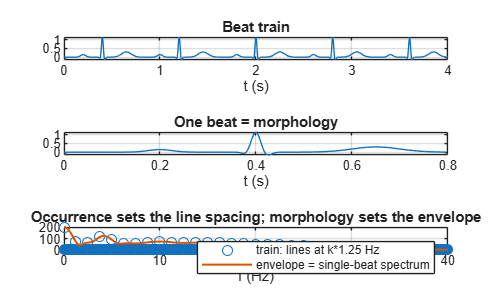

fs = 250;  Tb = 0.8;                                  % 75 beats/min
tb = 0:1/fs:Tb-1/fs;
beat = bump(tb,0.20,0.025, 0.15) + bump(tb,0.38,0.008,-0.15) ...
     + bump(tb,0.40,0.010, 1.20) + bump(tb,0.42,0.010,-0.25) ...
     + bump(tb,0.65,0.050, 0.30);

M     = 12;                                           % number of beats
train = repmat(beat, 1, M);
N     = numel(train);  tt = (0:N-1)/fs;  f = (0:N/2)*fs/N;

Xtrain = abs(fft(train));
Xbeat  = abs(fft(beat, N)) * M;                      % single beat, zero-padded, scaled to match lines

figure
tiledlayout(3,1)
nexttile, plot(tt, train), grid on, xlim([0 4]), xlabel('t (s)'), title('Beat train')
nexttile, plot(tb, beat), grid on, xlabel('t (s)'), title('One beat = morphology')
nexttile, plot(f, Xtrain(1:N/2+1), 'o'), hold on
plot(f, Xbeat(1:N/2+1), 'LineWidth', 1.2), xlim([0 40]), grid on
xlabel('f (Hz)'), legend('train: lines at k*1.25 Hz', 'envelope = single-beat spectrum')
title('Occurrence sets the line spacing; morphology sets the envelope')

## 4.7 Change occurrence only vs change morphology only

(a) Change the rate (60 -> 100 bpm): the lines move, the envelope shape is the same. (b) Widen the QRS complex (same rate): the envelope loses high-frequency energy.

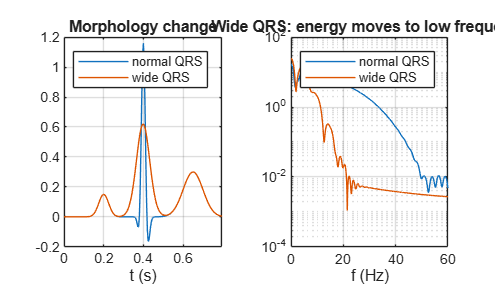

beatWide = bump(tb,0.20,0.025, 0.15) + bump(tb,0.38,0.030,-0.15) ...
         + bump(tb,0.40,0.035, 0.90) + bump(tb,0.42,0.030,-0.20) ...
         + bump(tb,0.65,0.050, 0.30);

Nz = 8192;  fz = (0:Nz/2)*fs/Nz;
Eb = abs(fft(beat,     Nz));
Ew = abs(fft(beatWide, Nz));

figure
tiledlayout(1,2)
nexttile, plot(tb, beat, tb, beatWide), grid on, legend('normal QRS', 'wide QRS'), xlabel('t (s)')
title('Morphology change')
nexttile, semilogy(fz, Eb(1:Nz/2+1), fz, Ew(1:Nz/2+1)), xlim([0 60]), grid on
xlabel('f (Hz)'), legend('normal QRS', 'wide QRS'), title('Wide QRS: energy moves to low frequency')


% Discussion:
%   - Rate is read from where the lines are (and from the fundamental).
%   - Waveform shape is read from the envelope (and from the phase).
%   - Neither is available if you only count "how many events happen".

## Exercises

1. Compute the DTFT of x[n] = (0.8)^n cos(0.3*pi*n) u[n] numerically and locate the peak. How does the peak change when the base 0.8 becomes 0.95? 2. For section 2.4, find the window length N that makes a 105 Hz tone leakage-free with fs = 1000 Hz. What condition must N satisfy? 3. In section 3.3, replace the hard mask by a smooth (raised-cosine) transition and compare the ringing in time. 4. Create a beat train with a random jitter in the beat times. What happens to the spectral lines and to the envelope? (Hint: jitter blurs occurrence, not morphology.) 5. Take the phase of the triangle wave and the magnitude of the square wave. Which one does the reconstruction resemble?

## Local functions

function [P, f] = welchSimple(x, L, fs)
% Averaged, Hann-windowed periodogram with 50% overlap (single-sided PSD).
    x = x(:).';
    step = floor(L/2);
    win  = 0.5*(1 - cos(2*pi*(0:L-1)/L));
    U    = sum(win.^2);
    starts = 1:step:(numel(x) - L + 1);
    P = zeros(1, floor(L/2)+1);
    for s = starts
        seg = x(s:s+L-1) .* win;
        Xs  = abs(fft(seg)).^2 / (fs*U);
        Xs  = Xs(1:floor(L/2)+1);
        Xs(2:end-1) = 2*Xs(2:end-1);
        P = P + Xs;
    end
    P = P / numel(starts);
    f = (0:floor(L/2))*fs/L;
end

function [fc, bw, H] = specFeatures(x, fs)
% Spectral centroid, bandwidth and normalized spectral entropy.
    x  = x(:).' - mean(x);
    N  = numel(x);
    X  = fft(x);
    P  = abs(X(1:floor(N/2)+1)).^2;
    f  = (0:floor(N/2))*fs/N;
    Pn = P / sum(P);
    fc = sum(f .* Pn);
    bw = sqrt(sum((f - fc).^2 .* Pn));
    q  = Pn(Pn > 0);
    H  = -sum(q .* log2(q)) / log2(numel(Pn));
end

function y = bump(t, mu, s, a)
% Gaussian bump of amplitude a, center mu, width s (building block for a synthetic beat).
    y = a * exp(-0.5*((t - mu)/s).^2);
end